# `（`1`）`isempty`函数（``★★★★☆``）`

A = [5 3 1 7 2 7];
x = 4;
ismember(x, A)

ans = logical
   1

% 等价于
~(isempty(find(A==x, 1)))

ans = logical
   1

# `（`2`）`unifrnd`函数（``★★★☆☆``）`

unifrnd(50,100,2)

ans =    87.7343   83.9851
   63.8013   82.7549


unifrnd(-3,3,1,3)

ans =    -2.0243   -2.2860   -0.0098


unifrnd(-3,3,[1,3])

ans =     2.7585   -0.9577    0.5116


# `（`3`）`normrnd`函数（``★★☆☆☆``）`

normrnd(10,2,2)

ans =     9.8181   12.3896
    9.4945   11.2121


normrnd(-5,1,3,4)

ans =    -4.4595   -4.7979   -3.6588   -3.6046
   -6.4449   -5.3479   -5.5808   -4.6790
   -5.9677   -3.7099   -4.1249   -3.3766


normrnd(-5,1,[3,4])

ans =    -3.9376   -4.8056   -4.9638   -4.7787
   -4.7859   -5.4149   -5.3646   -2.2696
   -4.1232   -4.6415   -3.2290   -5.2962


# `（`4`）`fibonacci`函数（``★☆☆☆☆``）`

% fibonacci(1:10)
% fibonacci(50)
fib_10 = 1/sqrt(5)*(((1+sqrt(5))/2).^(1:10)-((1-sqrt(5))/2).^(1:10))

fib_10 =     1.0000    1.0000    2.0000    3.0000    5.0000    8.0000   13.0000   21.0000   34.0000   55.0000


# `（`5`）`factorial`函数（``★★★☆☆``）`

factorial(10)

ans = 3628800

prod(1:10)

ans = 3628800

# `（`6`）`randperm`函数（``★★★★★``）`

randperm(10)

ans =      7     5     8     1     6     9     4     2     3    10


randperm(10,3)

ans =      7     4    10


# `（`7`）`randsample`函数（``★★★☆☆``）`

`（`1`）`y = randsample(n, k) `返回从整数` 1 `到` n `中无放回随机均匀抽取的` k `个值。`

y = randsample(n,k)等价于y = randperm(n,k)

 randsample(5,3)

ans =      4
     2
     3


 randperm(5,3)

ans =      2     3     4


  randsample(5,5) 

ans =      2
     1
     4
     5
     3


   randperm(5)

ans =      4     1     5     3     2


`（`2`）`y = randsample(n, k, true) `返回从整数` 1 `到` n `中有放回随机均匀抽取的` k `个值。`

y = randsample(n, k, true) 等价于y = randi(n, k, 1)

 randsample(5, 4, true) 

ans =      2
     4
     2
     5


randi(5, 4, 1)

ans =      5
     2
     3
     4


`（``3``）``y = randsample(population,k) ``返回一个向量，其中包含从向量`` population ``的值中``无放回``随机均匀抽取的`` k ``个值。`

population = [1 2 5 10 20 50 100];
randsample(population, 3) 

ans =     10    20     5


等价于

ind = randperm(length(population),3);
population(ind)

ans =     50     5    20


`（``4``）``y = randsample(population,k,true) ``返回一个向量，其中包含从向量`` population ``的值中``有放回``随机均匀抽取的`` k ``个值。`

population = [1 2 5 10 20 50 100];
randsample(population, 10, true) 

ans =      1     2     1    20     1     5   100    10     5     2


等价于

ind = randi(length(population),10,1);
population(ind)

ans =     10   100     1    10    50     1    20   100     2     1


`（``5``）``y = randsample(n,k,true,w) ``使用长度为`` n ``的非负权重向量`` w ``来确定整数`` i ``被选为`` y ``的输入项的概率。`

% 指定选中5的概率为0.4，4的概率为0.3，选中1、2、3的概率为0.1
randsample(5,3,true,[0.1 0.1 0.1 0.3 0.4])

ans =      5
     5
     5


`（``6``）``y = randsample(population,k,true,w)``使用与向量`` population ``长度相同的非负权重向量`` w ``来确定值`` population(i) ``被选为`` y ``的输入项的概率（这里一定是有放回的抽样，因此第三个输入参数只能为``true``）。`

population = [1 2 5 10 20 50 100];
w = [7 6 5 4 3 2 1];  % 权重向量的长度要和population相同
w/sum(w)  % 实际的概率

ans =     0.2500    0.2143    0.1786    0.1429    0.1071    0.0714    0.0357


randsample(population,10,true,w)

ans =     50     1    10     2     2     1    20     5    10    20


# `（8）`datasample`函数``（``★★☆☆☆``）`

x = randi(10,5,3)

x =      9     6     8
    10     3     8
    10     3     6
     5     4     4
     1     1     9


k = 3; 
dim = 1;  % dim等于1时表示沿着行方向进行随机抽取
datasample(x,k,dim,'Replace',false)  % 无放回抽样

ans =      5     4     4
     1     1     9
     9     6     8


dim = 2;  % dim等于2
datasample(x,k,dim,'Replace',true)  % 有放回抽样

ans =      6     8     8
     3     8     8
     3     6     6
     4     4     4
     1     9     9


# `（`9`）`ismembertol`函数（``★★☆☆☆``）`

创建向量 x。通过变换和取消变换 x 来获取第二个向量 y。此变换会向 y 中引入舍入误差。

x = (1:6)'*pi;
y = 10.^log10(x);

通过取差值来验证 x 和 y 不同。

x-y

ans = 1.0e-14 *

    0.0444
         0
         0
         0
         0
   -0.3553


使用 ismember 以查找 x 内位于 y 中的元素。ismember 函数执行精确比较并确定 x 中的某些矩阵元素不是 y 的成员。

lia = ismember(x,y)

lia = 6×1 logical 数组
   0
   1
   1
   1
   1
   0


使用 ismembertol 执行使用较小容差的比较。ismembertol 将容差范围内的元素视为相等元素并确定 x 中的所有元素都为 y 的成员。

LIA = ismembertol(x,y)

LIA = 6×1 logical 数组
   1
   1
   1
   1
   1
   1


# `（`10`）`uniquetol`函数（``★★☆☆☆``）`

创建向量 x。通过变换和取消变换 x 来获取第二个向量 y。此变换会向 y 中引入舍入误差。x = (1:6)'*pi;

y = 10.^log10(x);

通过取差值来验证 x 和 y 不同。

x-y

ans = 1.0e-14 *

    0.0444
         0
         0
         0
         0
   -0.3553


使用 unique 找出串联向量 [x;y] 中的唯一元素。unique 函数执行精确比较，并确定 x 中有些值与 y 中的值不完全相等。这些值与那些在 x-y 中具有非零差分的元素是同一批元素。因此，c 中包含一些*貌似*重复的值（实际上有细微差异）。

c = unique([x;y])

c =     3.1416
    3.1416
    6.2832
    9.4248
   12.5664
   15.7080
   18.8496
   18.8496


使用 uniquetol 应用一个较小的容差执行比较。uniquetol 会将处于容差范围内的元素视为相等。

C = uniquetol([x;y])

C =     3.1416
    6.2832
    9.4248
   12.5664
   15.7080
   18.8496


# `（`11`）`prctile`函数``（``★★★☆☆``）`

x = randi([-20,20],500,1)

x =     -8
     9
    -6
     9
    20
   -17
    -1
   -17
     9
    17


prctile(x,[25 50 75])  % 计算x向量的Q1 Q2 Q3

ans =   -10.5000   -1.0000   10.0000


X = randi([-20,20],50,3)

X =      8     4     3
     8   -20    -8
   -10    14    10
    -7   -16    -7
   -17    14    16
   -19    -7    -7
    11    -3    12
    -7    12    12
     1   -15   -18
    19     4    -4


prctile(X,25,1)  % 计算Q1

ans =     -7    -9    -9


ans =    -7.0000   -9.0000   -9.0000
    7.0000    7.0000   10.5000


# `（`12`）`meshgrid`函数（``★★★★☆``）`

% MATLAB生成网格坐标的代码
x = 0:4;
y = 0:3;
[xx,yy] = meshgrid(x,y)

xx =      0     1     2     3     4
     0     1     2     3     4
     0     1     2     3     4
     0     1     2     3     4


yy =      0     0     0     0     0
     1     1     1     1     1
     2     2     2     2     2
     3     3     3     3     3


z = xx.^2 + yy.^2

z =      0     1     4     9    16
     1     2     5    10    17
     4     5     8    13    20
     9    10    13    18    25


[X,Y] = meshgrid(1:3)

X =      1     2     3
     1     2     3
     1     2     3


Y =      1     1     1
     2     2     2
     3     3     3


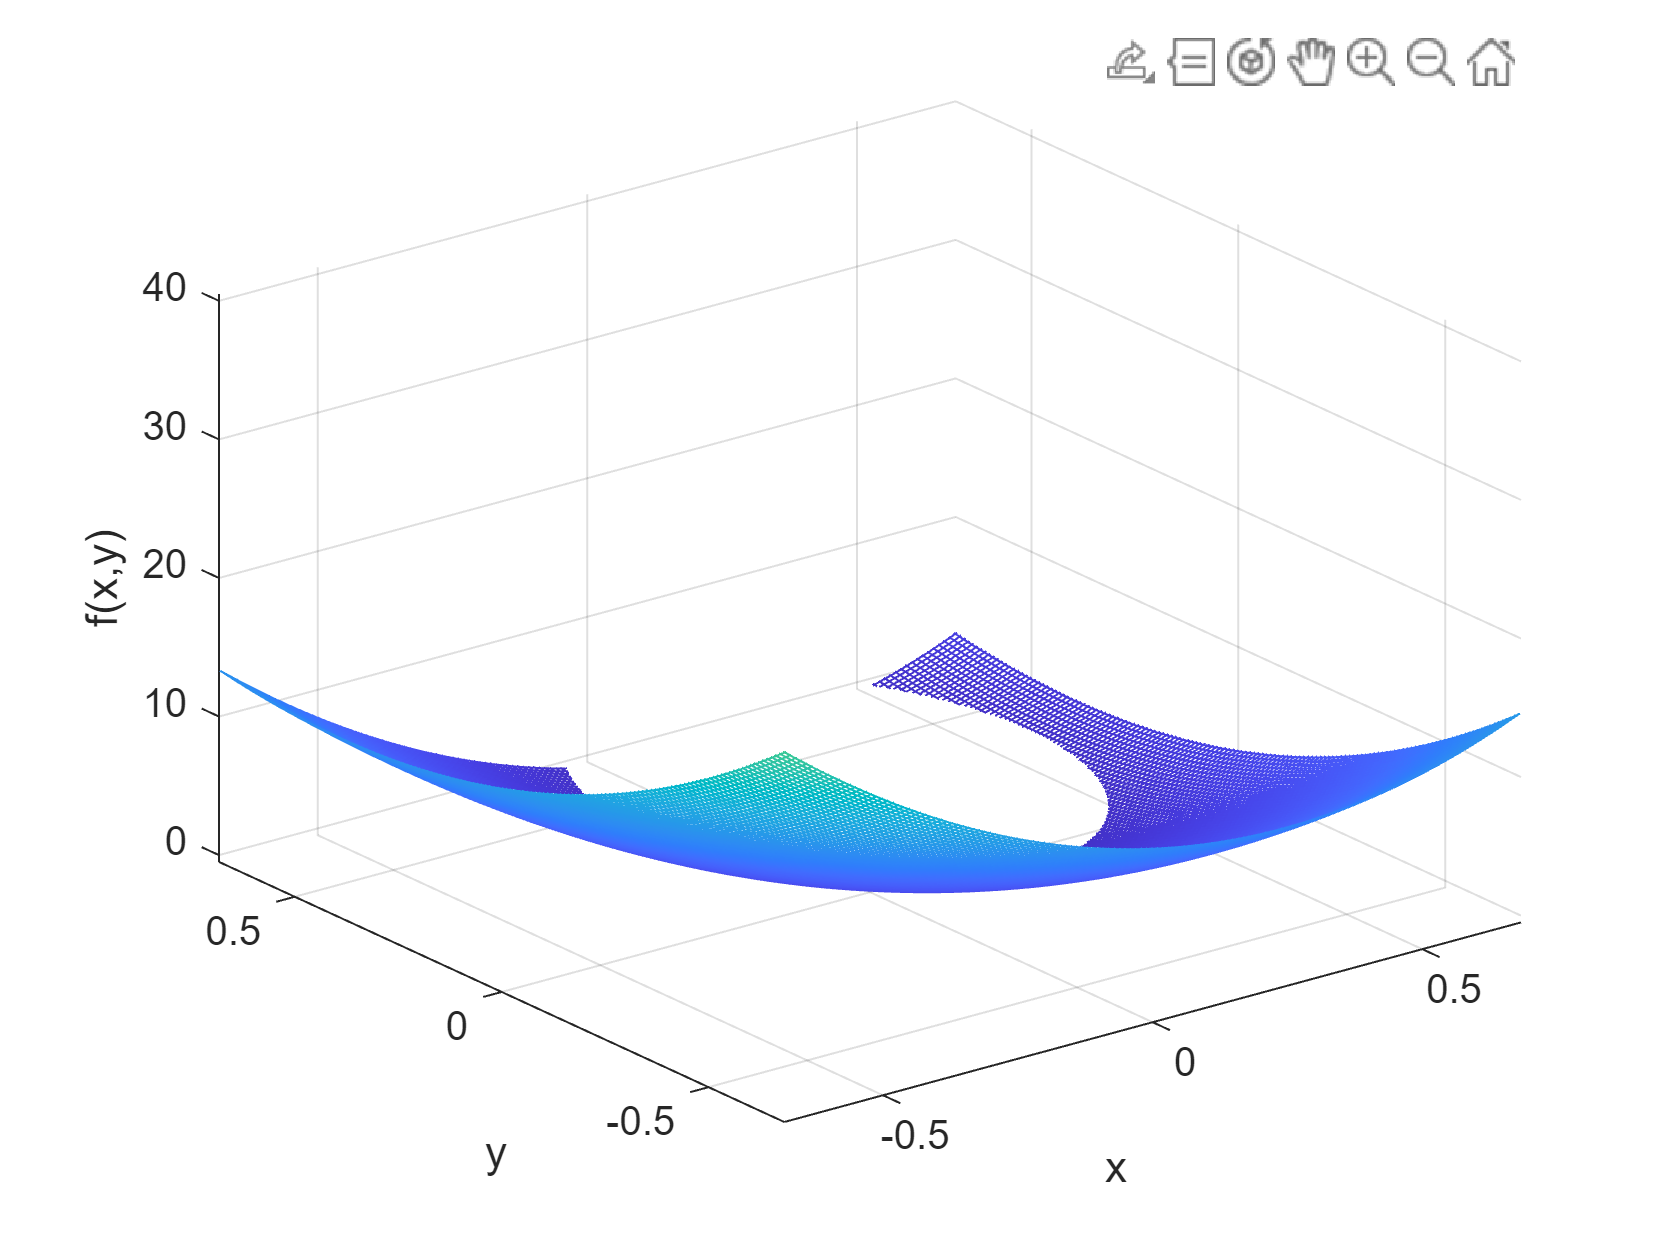

d = 0.01;
x = -1:d:1;
y = -1:d:1;
[x,y] = meshgrid(x,y);
z = x.^3 - y.^3 + 18 * x.^2 + 12 * y.^2 - 9 * x - 9 * y;
close all
mesh(x,y,z)
xlabel('x');ylabel('y');zlabel('f(x,y)')

# `（`13`）`rng`函数（``★★★★★``）`

seed = 100;
rng(seed)
randi(10,2,3)

ans =      6     5     1
     3     9     2


rng('shuffle')
randi(10,2,3)

ans =      6     4     6
     6    10     8


# `（`14`）`poissrnd`函数（``★★☆☆☆``）`

例子：假设某商店每天的客流量服从$\lambda $等于300的泊松分布，请模拟这个商店最近一个月每天的客流量。

p = poissrnd(300,1,30)

p =    290   293   296   301   324   326   316   292   271   287   315   303   302   296   307   299   310   292   299   318   301   317   279   284   299   283   283   316   329   280


mean(p)

ans = 300.2667

var(p)  % 样本方差

ans = 227.6506

var(p,1)  % 总体方差

ans = 220.0622

# `（`15`）`exprnd`函数（``★★☆☆☆``）`

假设某工厂生产的二极管的寿命服从均值为2000小时的指数分布，请随机生成1000个二极管的寿命，结果取整。

e = round(exprnd(2000,1,1000))

e =          145        2957         230        2640         952         972        1771        3696        1097        1282         136         304        1882         557        2431        2119         809         574        4855        4175        1617        4607         442        2077        2855        5389        4470        7350        1512        1323        3349        6624         624         134        2785        6712        1086         245        1512        2356         601        2713        3783        1799        2362         991         854         675        3037        2271


round(mean(e))

ans = 2023

round(var(e))  % 样本方差

ans = 4174999

round(var(e,1))  % 总体方差

ans = 4170824

# `（`16`）`nchoosek`函数（``★★★☆☆``）`

n = 5;
m = 2;
nchoosek(n,m)

ans = 10

nchoosek的第二种用法：

v = [2 4 6 8 10];
% 向量v中5个数，一次取其中2个的所有组合
nchoosek(v,2)

ans =      2     4
     2     6
     2     8
     2    10
     4     6
     4     8
     4    10
     6     8
     6    10
     8    10


# `（`17`）`perms`函数（``★★★☆☆``）`

v = [2 4 6];
P = perms(v)

P =      6     4     2
     6     2     4
     4     6     2
     4     2     6
     2     6     4
     2     4     6


x = [1 1 2 2];
perms(x)

ans =      2     2     1     1
     2     2     1     1
     2     1     2     1
     2     1     1     2
     2     1     2     1
     2     1     1     2
     2     2     1     1
     2     2     1     1
     2     1     2     1
     2     1     1     2


x = 1:7;
perms(x)

ans =      7     6     5     4     3     2     1
     7     6     5     4     3     1     2
     7     6     5     4     2     3     1
     7     6     5     4     2     1     3
     7     6     5     4     1     3     2
     7     6     5     4     1     2     3
     7     6     5     3     4     2     1
     7     6     5     3     4     1     2
     7     6     5     3     2     4     1
     7     6     5     3     2     1     4


prod(1:7)

ans = 5040

配套的讲解视频可在b站免费观看：

《MATLAB教程新手入门篇（数学建模清风主讲，适合零基础同学观看）》

[https://www.bilibili.com/video/BV1dN4y1Q7Kt/](https://www.bilibili.com/video/BV1dN4y1Q7Kt/)